# DC Motor System Identification 

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0x` and `x0y`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

clear; close all; clc;

R = 16;         % Electrical Resistance of motor in Ohms
V_max = 6.89;   % Maximum Electrical Voltage applied to motor
Ts = 0.01;      % Sampling Time for system

% Initial Guesses at Optimization Variables
L0 = 1;
J0 = 1;
b0 = 1;
Km0 = 1;

% Motor Parameters
A0 = 580;
A1 = 5.58;

% Load Motor Test Data Here
load("t.mat");
load("signal.mat");
load("L.mat");

% Modify Signal with motor parameters
signal(abs(signal) < A0) = 0;
signal(signal < 0) = signal(signal < 0) + A0;
signal(signal > 0) = signal(signal > 0) - A0;
Voltage = signal/max(abs(signal))*V_max;    % Converts into Volts
speed = L ./ (Ts * 14 * 20) * 2 * pi();     % Converts into rad/s

**Place these values and any other problem data into the workspace** by running this section before proceeding.

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

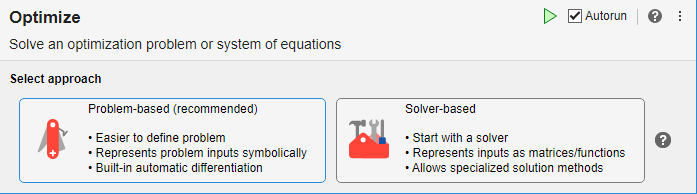

To get the problem-based task, click **Problem-based (recommended)**.

The following problem-based task has the variables, objective, and constraint filled in. Modify it for your problem, or run it as is to see how the task works. To modify the problem, click the **Define problem** button at the bottom of the task. To run the task, click the **Solve problem** button at the bottom of the task.

% Create optimization variables
J2 = optimvar("J","LowerBound",0);
L2 = optimvar("L","LowerBound",0,"UpperBound",1E-3);
b2 = optimvar("b","LowerBound",0);
Km2 = optimvar("Km","LowerBound",0);

% Set initial starting point for the solver
initialPoint.J = J0;
initialPoint.L = L0;
initialPoint.b = b0;
initialPoint.Km = Km0;

% Create problem
problem = optimproblem;

% Define problem objective
problem.Objective = fcn2optimexpr(@minResidual,J2,L2,b2,R,Km2,t,Voltage,speed);

% Display problem information
show(problem);


  OptimizationProblem : 

	Solve for:
       J, Km, L, b

	minimize :
       arg1

       where:

           arg1 = minResidual(J, L, b, 34, Km, extraParams{1}, extraParams{2}, extraParams{3});

       


% Solve problem
[solution,objectiveValue,reasonSolverStopped] = solve(problem,initialPoint);

Solving problem using fmincon.

Feasible point with lower objective function value found.


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Display results
solution

solution = struct with fields:
     J: 0.0038
    Km: 0.2152
     L: 3.8307e-04
     b: 0.0403


reasonSolverStopped

reasonSolverStopped =     StepSizeBelowTolerance


objectiveValue

objectiveValue = 8.6703e+04


% Clear variables
clearvars J2 L2 b2 Km2 initialPoint reasonSolverStopped objectiveValue

## Interpret Results

Plot the data and the fitted model response

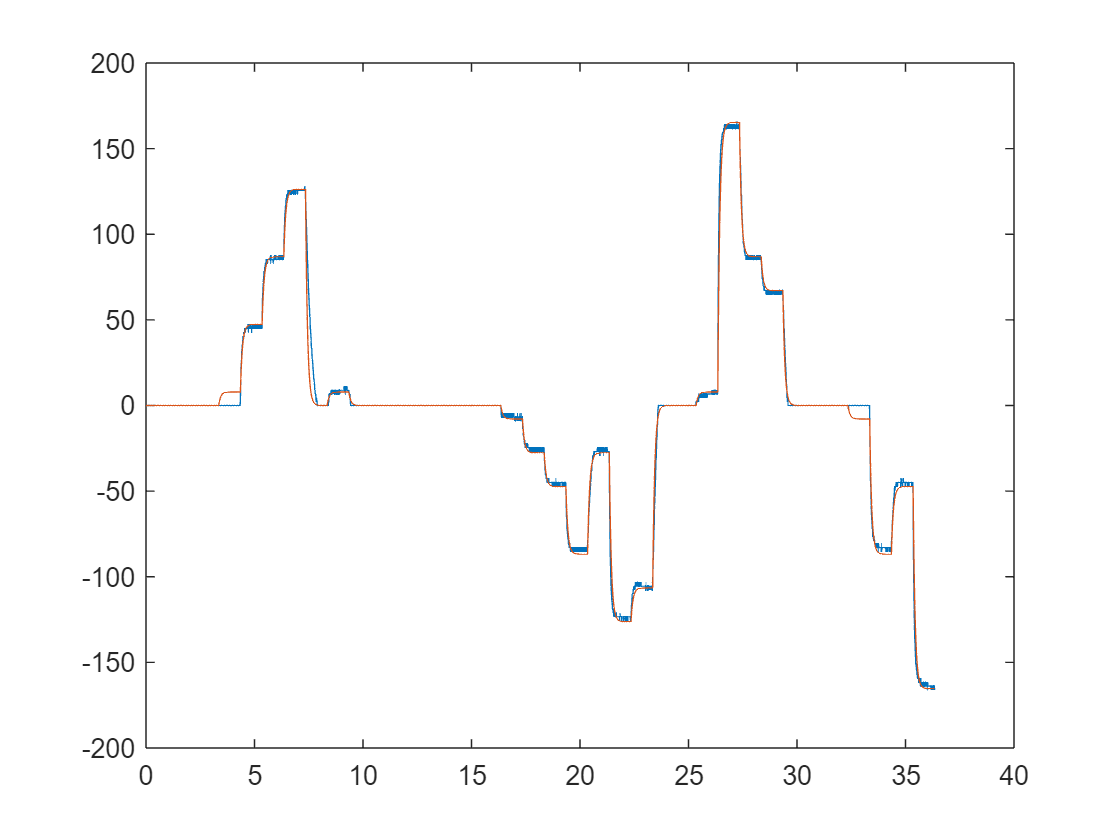

% Get optimal parameters
J_opt = solution.J;
L_opt = solution.L;
b_opt = solution.b;
Km_opt = solution.Km;

% Build statespace model from optimal fit parameters
h1 = tf(Km_opt, [L_opt R]);
h2 = tf(1 , [J_opt b_opt]);
dcMotorStatespace = ss(h2) * [h1, 1];
dcMotorStatespace = feedback(dcMotorStatespace,Km_opt, 1, 1);

u = [zeros(size(t)) Voltage];

% Compute simulated response and plot
w_sim = lsim(dcMotorStatespace,u,t,[0 0],'zoh');
plot(t,speed);
hold on;
plot(t,w_sim);

## Helper Functions

function objective = minResidual(J,L,b,R,Km,t,V,w)
% This function should return a scalar representing an optimization objective.

% Build statespace model
h1 = tf(Km, [L R]);
h2 = tf(1 , [J b]);
dcMotorStatespace = ss(h2) * [h1, 1];
dcMotorStatespace = feedback(dcMotorStatespace,Km, 1, 1);

u = [zeros(size(t)) V];

% Compute state space model response to signal
w_sim = lsim(dcMotorStatespace,u,t,[0 0],'zoh');

% Compute sum squared error between statespace and actual data
objective = sum((w_sim - w).^2);
end
